**Task 2**

clc, clear, close all
I1 = rgb2gray(imread('DSC_0597.png'));
I2 = rgb2gray(imread('DSC_0600.png'));
% [mp, fp] = cpselect(I1, I2, 'Wait', true);

load('mp.mat')
load('fp.mat')

t = fitgeotrans(mp, fp, 'projective');

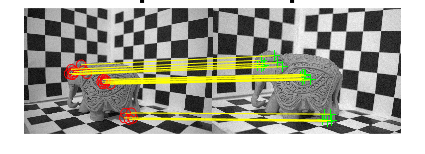

figure()
ax = axes;
showMatchedFeatures(I1, I2, mp, fp, 'montage', 'Parent', ax);
title(ax, 'Manual correspondence point matches', 'Fontsize', 18)